%==========================================================================
% Author:    Naghmeh Akhavan, PhD
% Affil.:    University of Michigan, Ann Arbor
% Contact:   nakhavan@umich.edu
%
%
% Last updated: March 2026
%==========================================================================

close all; clear; clc;

%% --------------------------- USER PATHS -------------------------------
combinedFolder  = 'C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out';
matR            = fullfile(combinedFolder,'Combined_BigResultTable.mat');
matD            = fullfile(combinedFolder,'Combined_BigStageDetailsTable.mat');

%% ----------------------------- KNOBS ----------------------------------
WAKE_BREAK_MIN  = 2;                % minutes
WAKE_BREAK_SEC  = WAKE_BREAK_MIN*60;

SAVE_FIG = true;
SAVE_TAB = true;

% Example: 3 bins over normalized sleep time
decileEdges01 = linspace(0,1,4);   % for 10 bins change 4 --> 11
nDec          = numel(decileEdges01)-1;
decileMidsPct = 100*(decileEdges01(1:end-1)+decileEdges01(2:end))/2;

% Subject cycle-count IQR filter
APPLY_SUBJECT_CYCLECOUNT_IQR_FILTER = true;
IQR_K = 1.5;   

%% ---------------------- LOAD COMBINED TABLES --------------------------
assert(isfile(matR), 'Missing file: %s', matR);
assert(isfile(matD), 'Missing file: %s', matD);

SR = load(matR);
SD = load(matD);

assert(isfield(SR,'Combined_BigResultTable'), ...
    'Combined_BigResultTable not found in %s', matR);
assert(isfield(SD,'Combined_BigStageDetailsTable'), ...
    'Combined_BigStageDetailsTable not found in %s', matD);

R = SR.Combined_BigResultTable;
D = SD.Combined_BigStageDetailsTable;

fprintf('Loaded:\n  %s\n  %s\n', matR, matD);

Loaded:
  C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out\Combined_BigResultTable.mat
  C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out\Combined_BigStageDetailsTable.mat



%% --------------------- NORMALIZE RESULT TABLE -------------------------
assert(ismember('Subject_Index', R.Properties.VariableNames), ...
    'R is missing Subject_Index.');

R.Subject_Index = string(R.Subject_Index);

if ~ismember('REM_Cycle_Index', R.Properties.VariableNames)
    R.REM_Cycle_Index = strings(height(R),1);
end
R.REM_Cycle_Index = string(R.REM_Cycle_Index);

% Ensure needed numeric columns exist
needR = {'IREM','NREM','Wake','Movement'};
for k = 1:numel(needR)
    v = needR{k};
    if ~ismember(v, R.Properties.VariableNames)
        R.(v) = NaN(height(R),1);
    end
    R.(v) = double(R.(v));
end

% If IREM missing or all-NaN, reconstruct from NREM + Wake + Movement
if ~ismember('IREM', R.Properties.VariableNames) || all(isnan(R.IREM))
    if all(ismember({'NREM','Wake','Movement'}, R.Properties.VariableNames))
        R.IREM = double(R.NREM) + double(R.Wake) + double(R.Movement);
        fprintf('IREM reconstructed as NREM + Wake + Movement.\n');
    else
        error('Cannot reconstruct IREM: missing NREM/Wake/Movement.');
    end
else
    R.IREM = double(R.IREM);
end

%% --------------------- FIND REM DURATION COLUMN -----------------------
candREM = {'REMdur','REMpost','REM','REM_Duration','REMlen','REM_sec','REMduration'};
haveREM = candREM(ismember(candREM, R.Properties.VariableNames));

if isempty(haveREM)
    error('No REM duration column found. Looked for: %s', strjoin(candREM, ', '));
end

REMcolName = haveREM{1};
R.(REMcolName) = double(R.(REMcolName));
fprintf('Using "%s" as REM duration column.\n', REMcolName);

Using "REMpost" as REM duration column.



%% ---------------- NORMALIZE STAGE-DETAILS TABLE -----------------------
assert(ismember('Stage', D.Properties.VariableNames), ...
    'Stage column not found in stage table.');
assert(ismember('Duration', D.Properties.VariableNames), ...
    'Duration column not found in stage table.');
assert(ismember('REM_Cycle_Index', D.Properties.VariableNames), ...
    'Stage table missing REM_Cycle_Index.');

D.Stage           = double(D.Stage);
D.Duration        = double(D.Duration);
D.REM_Cycle_Index = string(D.REM_Cycle_Index);

if ~ismember('ord', D.Properties.VariableNames)
    D.ord = (1:height(D))';
end

D = sortrows(D, {'REM_Cycle_Index','ord'});

%% ---------------------- LONG-WAKE DROP -------------------------------
WAKE_CODE = 5;   

[Gd, keys]  = findgroups(D.REM_Cycle_Index);
hasLongWake = false(numel(keys),1);

for gi = 1:numel(keys)
    rows = (Gd == gi);
    st   = D.Stage(rows);
    du   = D.Duration(rows);

    if any(isfinite(st) & isfinite(du) & (st == WAKE_CODE) & (du >= WAKE_BREAK_SEC))
        hasLongWake(gi) = true;
    end
end

FlagTab = table(keys, hasLongWake, ...
    'VariableNames', {'REM_Cycle_Index','HasLongWake'});

R = outerjoin(R, FlagTab, ...
    'Keys', 'REM_Cycle_Index', ...
    'MergeKeys', true, ...
    'Type', 'left');

if ~ismember('HasLongWake', R.Properties.VariableNames)
    R.HasLongWake = false(height(R),1);
else
    R.HasLongWake = logical(fillmissing(double(R.HasLongWake), 'constant', 0));
end

maskDropLW = (R.HasLongWake == 1);
nDropLW    = sum(maskDropLW);
Rkeep      = R(~maskDropLW, :);

fprintf(['Long-wake DROP applied: Wake >= %d min (>= %d sec)\n' ...
         '  Dropped cycles: %d\n' ...
         '  Kept cycles after LW filter: %d\n'], ...
         WAKE_BREAK_MIN, WAKE_BREAK_SEC, nDropLW, height(Rkeep));

Long-wake DROP applied: Wake >= 2 min (>= 120 sec)
  Dropped cycles: 1028
  Kept cycles after LW filter: 3994



%% ---------------------- VALID CYCLE FILTER ---------------------------
for v = {'Subject_Index','IREM',REMcolName}
    assert(ismember(v{1}, Rkeep.Properties.VariableNames), ...
        'Missing %s after LW filtering.', v{1});
end

Rkeep.Subject_Index = string(Rkeep.Subject_Index);
Rkeep.IREM          = double(Rkeep.IREM);
Rkeep.(REMcolName)  = double(Rkeep.(REMcolName));

valid = isfinite(Rkeep.IREM) & (Rkeep.IREM >= 0) & ...
        isfinite(Rkeep.(REMcolName)) & (Rkeep.(REMcolName) > 0) & ...
        strlength(strtrim(Rkeep.Subject_Index)) > 0;

Rkeep = Rkeep(valid,:);

assert(~isempty(Rkeep), ...
    'No valid cycles remain after LW filtering and validity checks.');

fprintf('Valid cycles after LW filtering: %d\n', height(Rkeep));

Valid cycles after LW filtering: 3722



%% -------- SUBJECT CYCLE-COUNT IQR OUTLIER FILTER (HUMAN ONLY) --------
removedSubjects = strings(0,1);
cycleCountTab   = table();

if APPLY_SUBJECT_CYCLECOUNT_IQR_FILTER
    [Gs, subjNames] = findgroups(Rkeep.Subject_Index);
    cycleCounts     = splitapply(@numel, Rkeep.Subject_Index, Gs);

    cycleCountTab = table(subjNames, cycleCounts, ...
        'VariableNames', {'Subject_Index','KeptCycleCount'});

    q1  = local_quantile(cycleCounts, 0.25);
    q3  = local_quantile(cycleCounts, 0.75);
    iqrVal = q3 - q1;

    lo = q1 - IQR_K*iqrVal;
    hi = q3 + IQR_K*iqrVal;

    isOutlierSubject = (cycleCounts < lo) | (cycleCounts > hi);
    removedSubjects  = subjNames(isOutlierSubject);

    fprintf(['Subject cycle-count IQR filter:\n' ...
             '  Q1 = %.3f, Q3 = %.3f, IQR = %.3f\n' ...
             '  Lower bound = %.3f, Upper bound = %.3f\n' ...
             '  Outlier subjects removed = %d of %d\n'], ...
             q1, q3, iqrVal, lo, hi, sum(isOutlierSubject), numel(subjNames));

    if ~isempty(removedSubjects)
        Rkeep = Rkeep(~ismember(Rkeep.Subject_Index, removedSubjects), :);
        fprintf('  Cycles remaining after subject outlier removal: %d\n', height(Rkeep));
    else
        fprintf('  No subject removed by cycle-count IQR filter.\n');
    end
else
    fprintf('Subject cycle-count IQR filter: OFF\n');
end

Subject cycle-count IQR filter:
  Q1 = 3.000, Q3 = 9.000, IQR = 6.000
  Lower bound = -6.000, Upper bound = 18.000
  Outlier subjects removed = 20 of 541


  Cycles remaining after subject outlier removal: 3217



assert(~isempty(Rkeep), 'No cycles remain after subject outlier filtering.');

%% ------------------- GROUPS AFTER ALL FILTERING -----------------------
[ G, recNames ] = findgroups(Rkeep.Subject_Index);

sumREM_bin  = zeros(nDec,1);   % pooled REM time per bin
sumTOT_bin  = zeros(nDec,1);   % pooled total bin duration
subjFracREM = NaN(numel(recNames), nDec);
used        = false(numel(recNames),1);

%% ------------------ PER-SUBJECT NORMALIZED-BIN STATS -----------------
for gi = 1:numel(recNames)
    idx  = find(G == gi);

    IREM = Rkeep.IREM(idx);
    REM  = Rkeep.(REMcolName)(idx);

    cycDur = IREM + REM;
    cycDur(~isfinite(cycDur)) = 0;

    sCum = [0; cumsum(cycDur)];
    totalNight = sCum(end);

    if totalNight <= 0
        continue;
    end

    binAbsEdges = decileEdges01 * totalNight;   % absolute time edges in sec

    % REM interval within each cycle:
    % [start of REM, end of REM]
    REM_st = sCum(1:end-1) + IREM;
    REM_en = REM_st + REM;

    for d = 1:nDec
        a = binAbsEdges(d);
        b = binAbsEdges(d+1);
        binDur = b - a;

        if binDur <= 0
            continue;
        end

        rem_in_bin = 0;
        for c = 1:numel(REM_st)
            rem_in_bin = rem_in_bin + overlap_len(REM_st(c), REM_en(c), a, b);
        end

        sumREM_bin(d) = sumREM_bin(d) + rem_in_bin;
        sumTOT_bin(d) = sumTOT_bin(d) + binDur;

        subjFracREM(gi,d) = rem_in_bin / binDur;
    end

    used(gi) = true;
end

nSubj = sum(used);
if nSubj == 0
    error('No subjects with computable REM fractions after all filtering.');
end

fprintf('Subjects used in final analysis: %d\n', nSubj);

Subjects used in final analysis: 521


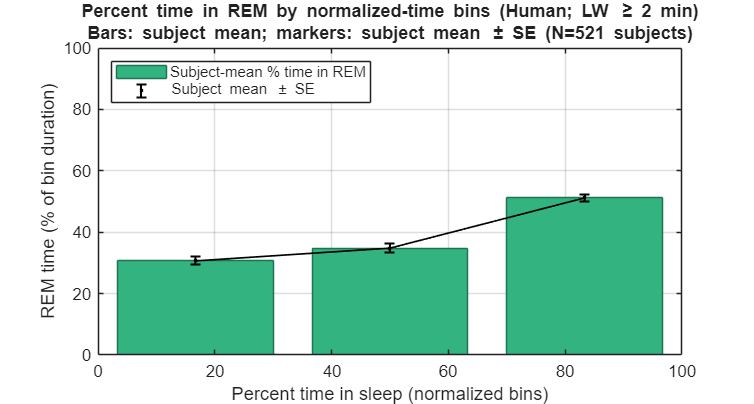

Saved figure:
  C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out\tables_out\Fig_REM_percentTime_longwake2min_IQRsubj_fromCombined.png



%% ------------------- SUBJECT-AVERAGE BAR + SE ------------------------
meanSubj_pct = 100 * mean(subjFracREM(used,:), 1, 'omitnan');
seSubj_pct   = 100 * std(subjFracREM(used,:), 0, 1, 'omitnan') / sqrt(nSubj);

barPct = meanSubj_pct;

fracREM_pooled     = sumREM_bin ./ max(sumTOT_bin, eps);
fracREM_pooled_pct = 100 * fracREM_pooled;

%% ----------------------------- PLOT ----------------------------------
figure('Color','w','Position',[100 100 860 460]);

bar(decileMidsPct, barPct, ...
    'FaceColor',[0.20 0.70 0.50], ...
    'EdgeColor',[0.12 0.45 0.32]);
hold on;

errorbar(decileMidsPct, meanSubj_pct, seSubj_pct, ...
         'k.', 'LineStyle','none', 'LineWidth',1.2);
plot(decileMidsPct, meanSubj_pct, 'k-', 'LineWidth',1);

xlabel('Percent time in sleep (normalized bins)');
ylabel('REM time (% of bin duration)');

ttl1 = sprintf('Percent time in REM by normalized-time bins (Human; LW \\geq %d min)', ...
               WAKE_BREAK_MIN);
ttl2 = sprintf('Bars: subject mean; markers: subject mean \\pm SE (N=%d subjects)', nSubj);
title({ttl1, ttl2}, 'Interpreter','tex');

ylim([0, 100]);
xlim([0, 100]);
grid on; box on;
legend({'Subject-mean % time in REM','Subject mean \pm SE'}, ...
       'Location','northwest');

if SAVE_FIG
    outDir = fullfile(combinedFolder,'tables_out');
    if ~isfolder(outDir), mkdir(outDir); end

    outPng = fullfile(outDir, ...
        sprintf('Fig_REM_percentTime_longwake%dmin_IQRsubj_fromCombined.png', WAKE_BREAK_MIN));

    try
        exportgraphics(gcf, outPng, 'Resolution', 300);
    catch
        print(gcf, outPng, '-dpng', '-r300');
    end

    fprintf('Saved figure:\n  %s\n', outPng);
end

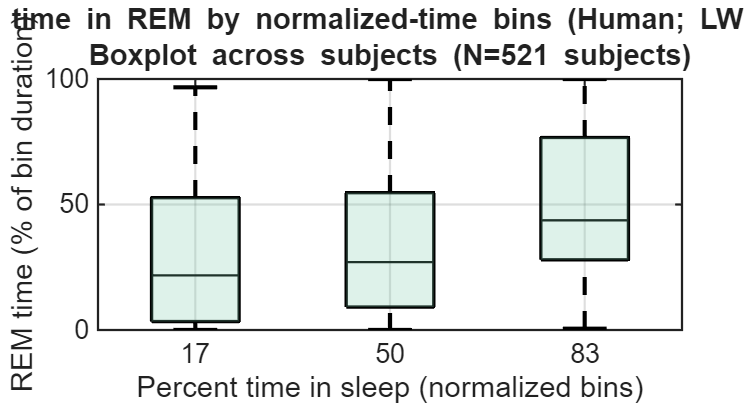

Saved boxplot figure:
  C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out\tables_out\Fig_REM_percentTime_BOXPLOT_longwake2min_IQRsubj_fromCombined.png



%% ---------------------- BOXPLOT + WHISKERS ---------------------------
figure('Color','w','Position',[120 140 860 460]);

% Subject-level REM percentages for each normalized-time bin
boxData_pct = 100 * subjFracREM(used,:);   % rows = subjects, cols = bins

% Labels at bin midpoints
lbl = strings(nDec,1);
for bi = 1:nDec
    lbl(bi) = sprintf('%.0f', decileMidsPct(bi));
end

boxplot(boxData_pct, ...
    'Labels', cellstr(lbl), ...
    'Symbol', 'k.', ...
    'Whisker', 1.5, ...
    'Colors', [0 0 0]);

% Enlarge outlier markers
hOut = findobj(gca,'Tag','Outliers');
set(hOut, 'Marker','o', 'MarkerSize',7, ...
    'MarkerEdgeColor','k', 'MarkerFaceColor','k');

grid on; box on;
xlabel('Percent time in sleep (normalized bins)');
ylabel('REM time (% of bin duration)');

ttl1 = sprintf('Percent time in REM by normalized-time bins (Human; LW \\geq %d min)', ...
               WAKE_BREAK_MIN);
ttl2 = sprintf('Boxplot across subjects (N=%d subjects)', nSubj);
title({ttl1, ttl2}, 'Interpreter','tex');

ylim([0, 100]);
set(gca,'FontSize',16);

% Thicken boxplot lines
set(gca,'LineWidth',1.3);
set(findobj(gca,'Tag','Box')    , 'LineWidth',2.0, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Median') , 'LineWidth',2.4, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Whisker'), 'LineWidth',2.5, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Cap')    , 'LineWidth',2.5, 'Color',[0 0 0]);

ax = gca;
hW = findobj(ax,'Tag','Whisker');
if isempty(hW)
    hW = [findobj(ax,'Tag','Upper Whisker'); findobj(ax,'Tag','Lower Whisker')];
end
set(hW,'LineWidth',2.5);

hC = findobj(ax,'Tag','Cap');
if isempty(hC)
    hC = [findobj(ax,'Tag','Upper Adjacent Value'); findobj(ax,'Tag','Lower Adjacent Value')];
end
set(hC,'LineWidth',2.5);

% Add light shaded fill using the green color
hold on;
COL = [0.20 0.70 0.50];
cFill = COL + (1 - COL)*0.35;

h = findobj(gca,'Tag','Box');
h = flipud(h); % match left-to-right bin order
for j = 1:numel(h)
    xd = get(h(j),'XData');
    yd = get(h(j),'YData');
    patch(xd, yd, cFill, 'FaceAlpha',0.25, 'EdgeColor','none');
end

med = findobj(gca,'Tag','Median');
set(med,'Color',[0 0 0],'LineWidth',1.4);
hold off;

if SAVE_FIG
    outDir = fullfile(combinedFolder,'tables_out');
    if ~isfolder(outDir), mkdir(outDir); end

    outPng_box = fullfile(outDir, ...
        sprintf('Fig_REM_percentTime_BOXPLOT_longwake%dmin_IQRsubj_fromCombined.png', WAKE_BREAK_MIN));

    try
        exportgraphics(gcf, outPng_box, 'Resolution', 300);
    catch
        print(gcf, outPng_box, '-dpng', '-r300');
    end

    fprintf('Saved boxplot figure:\n  %s\n', outPng_box);
end


%% --------------------------- SAVE TABLE -------------------------------
if SAVE_TAB
    outDir = fullfile(combinedFolder,'tables_out');
    if ~isfolder(outDir), mkdir(outDir); end

    T_out = table((1:nDec).', decileMidsPct(:), ...
        meanSubj_pct(:), seSubj_pct(:), repmat(nSubj,nDec,1), ...
        sumREM_bin(:), sumTOT_bin(:), ...
        fracREM_pooled(:), fracREM_pooled_pct(:), ...
        'VariableNames', {'Bin','MidPercent', ...
                          'Bar_SubjMean_REM_pct','SE_SubjMean_REM_pct','N_subjects', ...
                          'Pooled_REM_sec','Pooled_Total_sec', ...
                          'Pooled_REM_frac','Pooled_REM_pct'});

    outCsv = fullfile(outDir, ...
        sprintf('rem_percent_time_bins_longwake%dmin_IQRsubj_fromCombined.csv', WAKE_BREAK_MIN));
    writetable(T_out, outCsv);
    fprintf('Saved summary table:\n  %s\n', outCsv);

    % Save per-subject cycle counts and outlier flags too
    if APPLY_SUBJECT_CYCLECOUNT_IQR_FILTER && ~isempty(cycleCountTab)
        q1  = local_quantile(cycleCountTab.KeptCycleCount, 0.25);
        q3  = local_quantile(cycleCountTab.KeptCycleCount, 0.75);
        iqrVal = q3 - q1;
        lo = q1 - IQR_K*iqrVal;
        hi = q3 + IQR_K*iqrVal;

        cycleCountTab.LowerBound = repmat(lo, height(cycleCountTab), 1);
        cycleCountTab.UpperBound = repmat(hi, height(cycleCountTab), 1);
        cycleCountTab.IsOutlier  = cycleCountTab.KeptCycleCount < lo | ...
                                   cycleCountTab.KeptCycleCount > hi;

        outCsv2 = fullfile(outDir, ...
            sprintf('subject_cyclecount_IQRfilter_longwake%dmin.csv', WAKE_BREAK_MIN));
        writetable(cycleCountTab, outCsv2);
        fprintf('Saved subject cycle-count table:\n  %s\n', outCsv2);
    end
end

Saved summary table:
  C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out\tables_out\rem_percent_time_bins_longwake2min_IQRsubj_fromCombined.csv


Saved subject cycle-count table:
  C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out\tables_out\subject_cyclecount_IQRfilter_longwake2min.csv



fprintf('Done.\n');

Done.



%% ============================ FUNCTIONS ===============================
function L = overlap_len(a1,a2,b1,b2)
% Length of overlap between [a1,a2] and [b1,b2]
    if ~(isfinite(a1) && isfinite(a2) && isfinite(b1) && isfinite(b2)) || ...
            a2 <= a1 || b2 <= b1
        L = 0;
        return;
    end
    L = max(0, min(a2,b2) - max(a1,b1));
end

function q = local_quantile(x, p)
% Toolbox-free quantile approximation using linear interpolation.
% x must be numeric vector, p in [0,1].
    x = x(isfinite(x));
    if isempty(x)
        q = NaN;
        return;
    end
    x = sort(x(:));
    n = numel(x);

    if n == 1
        q = x;
        return;
    end

    pos = 1 + (n-1)*p;
    lo  = floor(pos);
    hi  = ceil(pos);

    if lo == hi
        q = x(lo);
    else
        q = x(lo) + (pos-lo)*(x(hi)-x(lo));
    end
end
